## Exercise 7.2

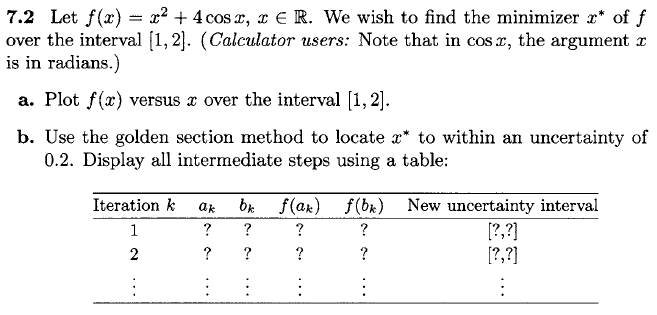

f = @(x) x^2+4*cos(x)

f = function_handle with value:
    @(x)x^2+4*cos(x)


x_lim = [1 2];

## a)

Plotting the function over the interval:

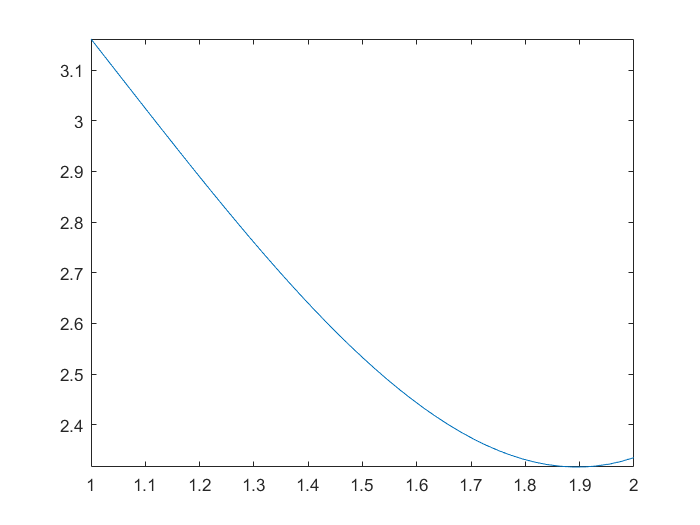

figure(1)
fplot(f,x_lim)

## b) Golden Search Method

The minimum number of steps required for the Golden Section with the uncertainty of $0\ldotp 2$ within the interval $\left\lbrack 1,2\right\rbrack$ is given by the inequality:


$$0\ldotp {61803}^N \ge \frac{\mathrm{final}\;\mathrm{range}}{\mathrm{initial}\;\mathrm{range}}\Longrightarrow 0\ldotp {61803}^N \le \frac{0\ldotp 2}{2-1}\;$$


uncertainty = 0.2

uncertainty = 0.2000

syms N
N = double(ceil(solve(0.61803^N==uncertainty/(x_lim(2)-x_lim(1)))))

N = 4

For each iteration, *f* is evaluated at two intermediate points $a_i$ and $b_i$:


$$\left\lbrack \begin{array}{c}
a_i  & b_i 
\end{array}\right\rbrack$$


The intermediate points of the next iteration is then given by:


$$a_{i+1} =a_i +\rho \left(b_i -a_i \right)$$



$$b_{i+1} =b_i +\left(1-\rho \right)\left(b_i -a_i \right)$$


Where $\rho \approx 0\ldotp 382$

% Initial interval definition
a_lim = 1;
b_lim = 2;

% Allocation of arrays
a = zeros(N,1)

a =      0
     0
     0
     0


b = zeros(N,1)

b =      0
     0
     0
     0


f_a = a;
f_b = b;
golden_search_summary = zeros(N,6)

golden_search_summary =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0



% Golden search method iterations
rho = 0.382

rho = 0.3820

for i=1:N
    a(i) = a_lim+rho*(b_lim-a_lim);  
    b(i) = a_lim+(1-rho)*(b_lim-a_lim);
    
    f_a(i) = f(a(i));
    f_b(i) =  f(b(i));
    
    if f_a(i) < f_b(i)
       a_lim;
       b_lim = b(i);
    else
        a_lim = a(i);
        b_lim;
    end
    
    golden_search_summary(i,:) = [a(i) b(i) f_a(i) f_b(i) a_lim b_lim];
end
golden_search_summary

golden_search_summary =     1.3820    1.6180    2.6606    2.4292    1.3820    2.0000
    1.6181    1.7639    2.4291    2.3437    1.6181    2.0000
    1.7640    1.8541    2.3437    2.3196    1.7640    2.0000
    1.8541    1.9098    2.3196    2.3171    1.8541    2.0000


From the summary table it is apparent that the interval for $x^\ast  =\left\lbrack a_4 ,b_0 \right\rbrack$

x_interval = [a_lim b_lim]

x_interval =     1.8541    2.0000


## Exercise 7.3

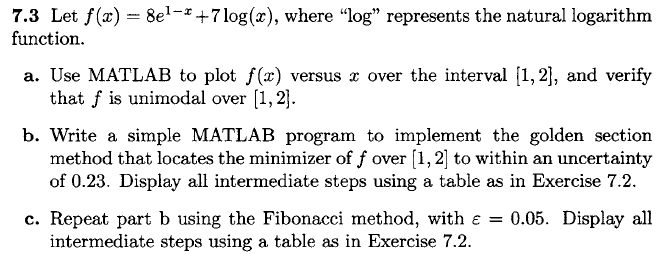

f = @(x) 8*exp(1-x)+7*log(x)

f = function_handle with value:
    @(x)8*exp(1-x)+7*log(x)


x_lim = [1 2];

## a)

Plotting the function over the interval:

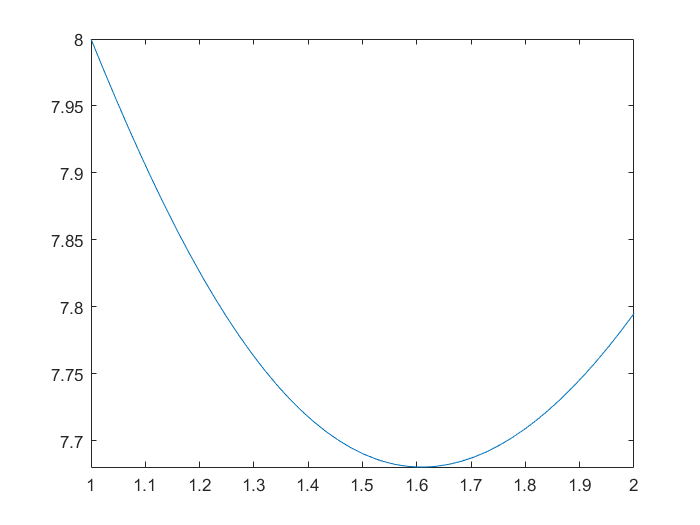

figure(2)
fplot(f,x_lim)

## b) Golden Search Method

The minimum number of steps required for the Golden Section with the uncertainty of $0\ldotp 2$ within the interval $\left\lbrack 1,2\right\rbrack$ is given by the inequality:


$$0\ldotp {61803}^N \ge \frac{\mathrm{final}\text{ }\mathrm{range}}{\mathrm{initial}\text{ }\mathrm{range}}\Longrightarrow 0\ldotp {61803}^N \ge \frac{0\ldotp 23}{2-1}\text{ }$$


uncertainty = 0.23

uncertainty = 0.2300

syms N
N = double(ceil(solve(0.61803^N==uncertainty/(x_lim(2)-x_lim(1)))))

N = 4

For each iteration, *f* is evaluated at two intermediate points $a_i$ and $b_i$:


$$\left\lbrack \begin{array}{c}
a_i  & b_i 
\end{array}\right\rbrack$$


The intermediate points of the next iteration is then given by:


$$a_{i+1} =a_0 +\rho \left(b_i -a_i \right)$$



$$b_{i+1} =b_0 +\left(1-\rho \right)\left(b_i -a_i \right)$$


Where $\rho \approx 0\ldotp 382$

% Initial interval definition
a_lim = 1;
b_lim = 2;

% Allocation of arrays
a = zeros(N,1);
b = zeros(N,1);
f_a = a;
f_b = b;
golden_search_summary = zeros(N,6);

% Golden search method iterations
rho = 0.382

rho = 0.3820

for i=1:N
    a(i) = a_lim+rho*(b_lim-a_lim);  
    b(i) = a_lim+(1-rho)*(b_lim-a_lim);
    
    f_a(i) = f(a(i));
    f_b(i) =  f(b(i));
    
    if f_a(i) < f_b(i)
       a_lim;
       b_lim = b(i);
    else
        a_lim = a(i);
        b_lim;
    end
    
    golden_search_summary(i,:) = [a(i) b(i) f_a(i) f_b(i) a_lim b_lim];
end
golden_search_summary

golden_search_summary =     1.3820    1.6180    7.7247    7.6805    1.3820    2.0000
    1.6181    1.7639    7.6805    7.6995    1.3820    1.7639
    1.5279    1.6180    7.6860    7.6805    1.5279    1.7639
    1.6181    1.6738    7.6805    7.6838    1.5279    1.6738


From the summary table it is apparent that the interval for $x^\ast  =\left\lbrack a_4 ,b_0 \right\rbrack$

x_interval = [a_lim b_lim]

x_interval =     1.5279    1.6738


## c) Fibonacci Method

The minimum number of steps required for the Fibonacci method with the uncertainty of $0\ldotp 23$ within the interval $\left\lbrack 1,2\right\rbrack$ is given by the inequality:


$$\frac{1+2\varepsilon }{F_{N+1} }\le \frac{\mathrm{final}\;\mathrm{range}}{\mathrm{initial}\;\mathrm{range}}\Longrightarrow \frac{1+2\varepsilon }{F_{N+1} }\le \frac{0\ldotp 23}{2-1}=\Longrightarrow F_{N+1} \le \frac{1+2\varepsilon }{0\ldotp 23}$$


% Finding the required number of iterations
% Solve() is not used since it was not working with the symbolic solve
epsilon = 0.05

epsilon = 0.0500

uncertainty = 0.23;
N = 0;
while fibonacci(N+1) < (1+2*epsilon) / (uncertainty / (x_lim(2)-x_lim(1)) )
   N = N + 1; 
end
N = N-1

N = 3

For each iteration, *f* is evaluated at two intermediate points $a_i$ and $b_i$:


$$\left\lbrack \begin{array}{c}
a_i  & b_i 
\end{array}\right\rbrack$$


The intermediate points of the next iteration is then given by:


$$a_{i+1} =a_0 +\rho \left(b_i -a_i \right)$$



$$b_{i+1} =b_0 +\left(1-\rho \right)\left(b_i -a_i \right)$$


Where $\rho$ is given by:


$$1-\rho_i =\frac{F_N }{F_{N+1} }$$


With the modification for the last iteration:


$$\rho_N =1-\left(0\ldotp 5+\varepsilon \right)$$


fibonacci_offset = 1; %Matlabs fibonacci method is off by one compared to book notation

% Initial interval definition
a_lim = 1;
b_lim = 2;

% Allocation of arrays
a = zeros(N,1);
b = zeros(N,1);
rho = zeros(N,1);
f_a = a;
f_b = b;
fibonacci_method_summary = zeros(N,7);
lower = '';

% Fibonacci method iterations
for i=1:N
    if(i==N)
        rho(i) = 1-(0.5+epsilon);
    else
        rho(i) = 1-fibonacci(N-i+1+fibonacci_offset)/fibonacci(N-i+2+fibonacci_offset);
    end
    
    if(lower=='a')
        a(i) = a_lim+rho(i)*(b_lim-a_lim);
        b(i) = a(i-1);
    elseif (lower=='b')
        b(i) = a_lim+(1-rho(i))*(b_lim-a_lim);
        a(i) = b(i-1);
    else
        a(i) = a_lim+rho(i)*(b_lim-a_lim);  
        b(i) = a_lim+(1-rho(i))*(b_lim-a_lim);
    end
    
    f_a(i) = f(a(i));
    f_b(i) =  f(b(i));
    
    if f_a(i) < f_b(i)
       lower = 'a';
       a_lim;
       b_lim = b(i);
    else
        lower = 'b';
        a_lim = a(i);
        b_lim;
    end
    
    fibonacci_method_summary(i,:) = [rho(i) a(i) b(i) f_a(i) f_b(i) a_lim b_lim];
end
fibonacci_method_summary

fibonacci_method_summary =     0.4000    1.4000    1.6000    7.7179    7.6805    1.4000    2.0000
    0.3333    1.6000    1.8000    7.6805    7.7091    1.4000    1.8000
    0.4500    1.5800    1.6000    7.6812    7.6805    1.5800    1.8000


From the summary table it is apparent that the interval for $x^\ast  =\left\lbrack a_4 ,b_0 \right\rbrack$

x_interval = [a_lim b_lim]

x_interval =     1.5800    1.8000


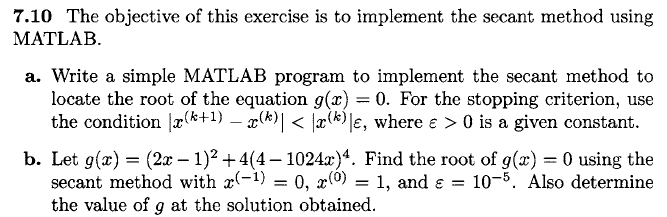

% Exercise specific definitions
g = @(x) (2*x-1)^2+4*(4-1024*x)^4;
x_curr = 0;
x_new = 1;
epsilon = 10^-5;

## a-b) Secant Method

For the Secant method, the value of *x* found in each iteration is given by:


$$x^{\left(k+1\right)} =\frac{g\left(x^{\left(k\right)} \right)x^{\left(k-1\right)} -g\left(x^{\left(k-1\right)} \right)x^{\left(k\right)} }{g\left(x^{\left(k\right)} \right)-g\left(x^{\left(k-1\right)} \right)}$$


% Secant method iterations (can be turned into a function)
while( abs(x_new-x_curr) > abs(x_curr)*epsilon )
    x_old = x_curr;
    x_curr = x_new;
    
    g_old = g(x_old);
    g_curr = g(x_curr);
    
    x_new = (g_curr*x_old-g_old*x_curr) / (g_curr-g_old);
end
x_root = x_new

x_root = 0.0039

g_root = g(x_root)

g_root = 0.9846

The found values are plotted to visualize the result:s


% not important....
figure(3)
fplot(g)

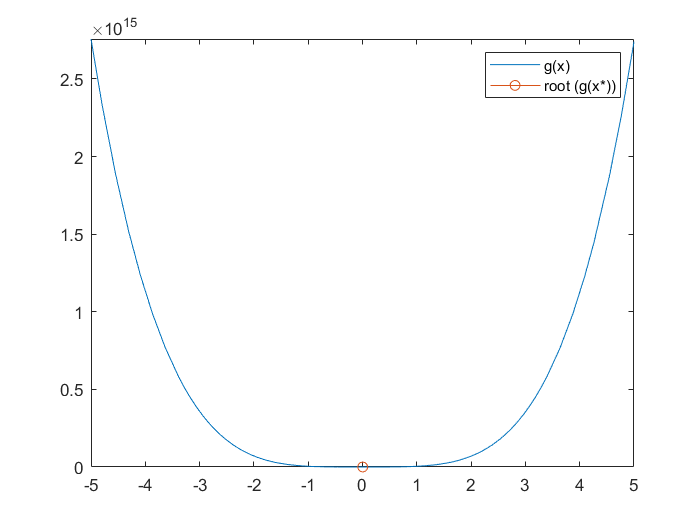

hold on
plot(x_root,g_root,'-o')
hold off
legend('g(x)','root (g(x*))')